clear; clc; close all;

### Data Extraction from structs

% Load data
rot = load("calib1_rotate.mat");
straight = load("calib2_straight.mat");

% Task 1
task1_1 = load("task1_1.mat");
task1_2 = load("task1_2.mat");
task1_3 = load("task1_3.mat");
task1_4 = load("task1_4.mat");
task1_5 = load("task1_5.mat");

% Task 2
task2_1 = load("task2_1.mat");
task2_2 = load("task2_2.mat");
task2_3 = load("task2_3.mat");
task2_4 = load("task2_4.mat");
task2_5 = load("task2_5.mat");

% Output file
outputFileName = 'calib_params.mat';

% Stationary Period in straight calibration
stationary_idx = find(straight.out.GT_time.time==60);
time = straight.out.GT_time.time;

## Accelerometer Calibration

Goal: Global x and y-axis should be 0 m/s^2, and z-axis should be 9.81 m/s^2 during stationary period (t<60s).

disp('------Start accelerometer calibration------')

------Start accelerometer calibration------


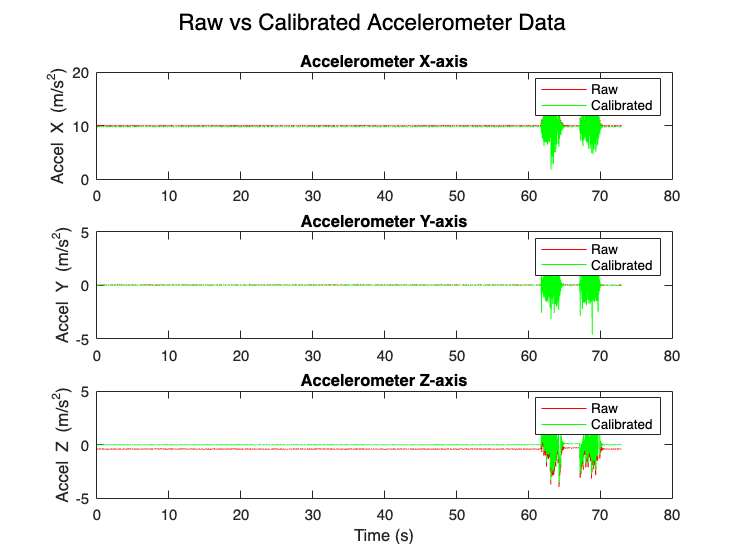

% Load data
% The first column flunctuates the least around gravity acceleration,
% indicating x-axis in sensor frame as z-axis in global frame

accel_raw = squeeze(straight.out.Sensor_ACCEL.signals.values)';
accel_stationary = accel_raw(1:stationary_idx,:);
g = [9.81, 0, 0];

% Find bias and variance
accel_mean = mean(accel_stationary);
accel_bias = accel_mean - g;             % Remove difference with gravity from Z
accel_var = var(accel_stationary);       % Determine noise in process model

% Calibrate full dataset
time_accel = straight.out.Sensor_ACCEL.time;
calib_accel = accel_raw - accel_bias;

figure;
subplot(3,1,1);
plot(time_accel, accel_raw(:,1), 'r'); hold on;
plot(time_accel, calib_accel(:,1), 'g');
ylabel('Accel X (m/s^2)');
legend('Raw', 'Calibrated');
title('Accelerometer X-axis');

subplot(3,1,2);
plot(time_accel, accel_raw(:,2), 'r'); hold on;
plot(time_accel, calib_accel(:,2), 'g');
ylabel('Accel Y (m/s^2)');
legend('Raw', 'Calibrated');
title('Accelerometer Y-axis');

subplot(3,1,3);
plot(time, accel_raw(:,3), 'r'); hold on;
plot(time, calib_accel(:,3), 'g');
ylabel('Accel Z (m/s^2)');
xlabel('Time (s)');
legend('Raw', 'Calibrated');
title('Accelerometer Z-axis');

sgtitle('Raw vs Calibrated Accelerometer Data');

disp('------End accelerometer calibration------')

------End accelerometer calibration------


## Gyroscope Calibration

Goal: Gyroscope should be 0 rad/s during stationary period (t<60s)

disp('------Start gyroscope calibration------')

------Start gyroscope calibration------


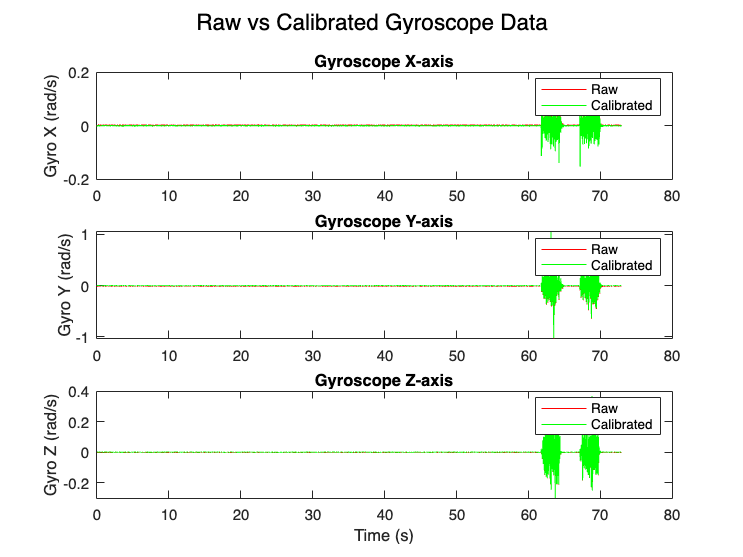

% Load data
gyro_raw = squeeze(straight.out.Sensor_GYRO.signals.values)';
gyro_stationary = gyro_raw(1:stationary_idx, :);

% Find bias and variance
gyro_bias = mean(gyro_stationary);
gyro_var = var(gyro_stationary);

% Calibrate full dataset
calib_gyro = gyro_raw-gyro_bias;
time_gyro = straight.out.Sensor_GYRO.time;

figure;
subplot(3,1,1);
plot(time_gyro, gyro_raw(:,1), 'r'); hold on;
plot(time_gyro, calib_gyro(:,1), 'g');
ylabel('Gyro X (rad/s)');
legend('Raw', 'Calibrated');
title('Gyroscope X-axis');

subplot(3,1,2);
plot(time_gyro, gyro_raw(:,2), 'r'); hold on;
plot(time_gyro, calib_gyro(:,2), 'g');
ylabel('Gyro Y (rad/s)');
legend('Raw', 'Calibrated');
title('Gyroscope Y-axis');

subplot(3,1,3);
plot(time_gyro, gyro_raw(:,3), 'r'); hold on;
plot(time_gyro, calib_gyro(:,3), 'g');
ylabel('Gyro Z (rad/s)');
xlabel('Time (s)');
legend('Raw', 'Calibrated');
title('Gyroscope Z-axis');

sgtitle('Raw vs Calibrated Gyroscope Data');

disp('------End gyroscope calibration------')

------End gyroscope calibration------


## ToF Calibration

Goal: calculate ToF offset using stationary period using reflection points to determine distance to wall

disp('------Start ToF calibration------')

------Start ToF calibration------


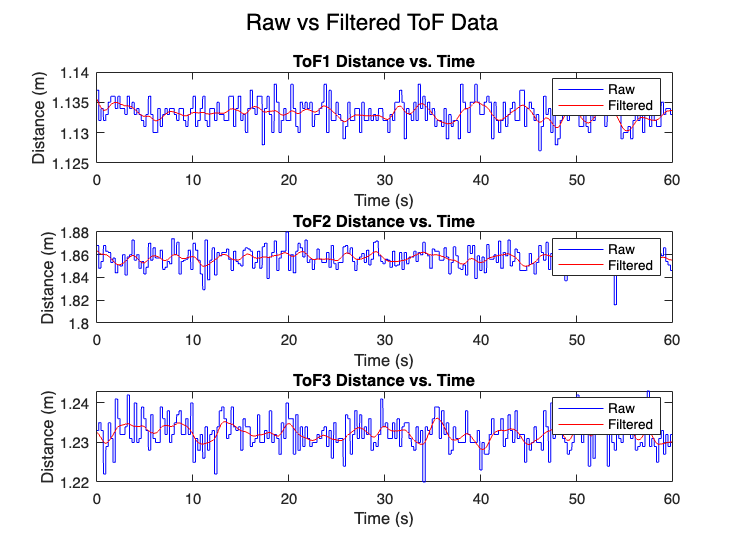

% Load data
% ToF1 = Right / ToF2 = Front / ToF3 = Left
ToF1_raw = straight.out.Sensor_ToF1.signals.values(1:stationary_idx,1);
ToF2_raw = straight.out.Sensor_ToF2.signals.values(1:stationary_idx,1);
ToF3_raw = straight.out.Sensor_ToF3.signals.values(1:stationary_idx,1);
stationaryTime = time(1:stationary_idx);

% Apply butterworth filter on noisy data before calibration
ToF1_filt = butterworth(ToF1_raw, 50, 0.1);
ToF2_filt = butterworth(ToF2_raw, 50, 0.1);
ToF3_filt = butterworth(ToF3_raw, 50, 0.1);
GT_position = straight.out.GT_position.signals.values(1:stationary_idx,:);

% Visualize raw values - noisy data
figure;
subplot(3,1,1)
plot(stationaryTime, ToF1_raw, 'b', stationaryTime, ToF1_filt, 'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('ToF1 Distance vs. Time')
legend('Raw', 'Filtered', 'Location','northeast')

subplot(3,1,2)
plot(stationaryTime, ToF2_raw, 'b', stationaryTime, ToF2_filt, 'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('ToF2 Distance vs. Time')
legend('Raw', 'Filtered', 'Location','northeast')

subplot(3,1,3)
plot(stationaryTime, ToF3_raw, 'b', stationaryTime, ToF3_filt, 'r')
xlabel('Time (s)')
ylabel('Distance (m)')
title('ToF3 Distance vs. Time')
legend('Raw', 'Filtered', 'Location','northeast')
sgtitle('Raw vs Filtered ToF Data');


% Find left/right and front ToF offset
L = 2.4;
[x_offset, theta_rad] = optimizeOffsetLR(GT_position(:, 1:2), ToF3_filt, ToF1_filt, L);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          3           46.9321                              786
     1          6           21.2122       0.0327349         2.69e-09      

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>

Estimated lateral offset: 0.0173 m
Estimated yaw angle: 0.0000 rad (0.00 deg)


front_bias = optimizeOffsetF(GT_position(:, 1:2), ToF2_filt, theta_rad, L/2);       % Assume front wall is at y = 1.2 m


Front ToF offset: -0.2663 m



%[calib_left, calib_right, calib_front] = applyToFCalibration(tof_bias, theta_offset, tof1, tof2, tof3)

% Configure optimized offsets for export
% tof_bias = [ToF1 (right) ToF2 (front) ToF3 (left)]
tof_bias = [x_offset front_bias x_offset]

tof_bias =     0.0173   -0.2663    0.0173


theta_offset = theta_rad

theta_offset = 4.8779e-10


tof1_var = var(ToF1_raw(ToF1_raw~=0 & ~isnan(ToF1_raw)));
tof2_var = var(ToF2_raw(ToF2_raw~=0 & ~isnan(ToF2_raw)));
tof3_var = var(ToF3_raw(ToF3_raw~=0 & ~isnan(ToF3_raw)));
tof_var = [tof1_var tof2_var tof3_var];

disp('------End ToF calibration------')

------End ToF calibration------


## Magnetometer Calibration

Goal: Calculate soft iron (A) and hard iron (b) matrices using magcal() for nonlinear least-squares fitting in 3D

disp('------Magnetometer calibration------')

------Magnetometer calibration------


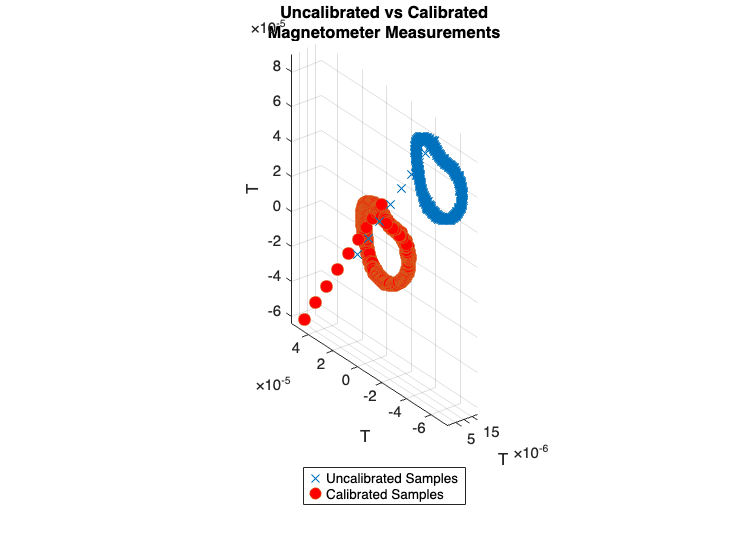

% Load data: only calibration that uses rotation
time_rot = rot.out.Sensor_MAG.time;
mag_raw = squeeze(rot.out.Sensor_MAG.signals.values)';
mag_raw = butterworth(mag_raw, 50, 3);  % Filter smoothing
GT_yaw = rot.out.GT_rotation.signals.values;

% (1) Matlab magcal approach - outputted for final calibration parameters
[A,b,expmfs] = magcal(mag_raw);         % Calibration coefficients
expmfs;                                 % Display the expected magnetic field strength in uT

% Calibrated data with soft and hard iron matrices
mag_cal = (mag_raw-b)*A; 
figure;
plot3(mag_raw(:,1),mag_raw(:,2),mag_raw(:,3),"LineStyle","none","Marker","X","MarkerSize",8)
hold on
grid(gca,"on")
plot3(mag_cal(:,1),mag_cal(:,2),mag_cal(:,3),"LineStyle","none","Marker","o", ...
      "MarkerSize",8,"MarkerFaceColor","r")
axis equal
xlabel("T")
ylabel("T")
zlabel("T")
legend("Uncalibrated Samples","Calibrated Samples","Location","southoutside")
title("Uncalibrated vs Calibrated" + newline + "Magnetometer Measurements")


% Compare yaw angle of sensor vs. ground truth
disp('Note: World frame is [Z,Y,X] using axis from sensor frame [X,Y,Z]')

Note: World frame is [Z,Y,X] using axis from sensor frame [X,Y,Z]


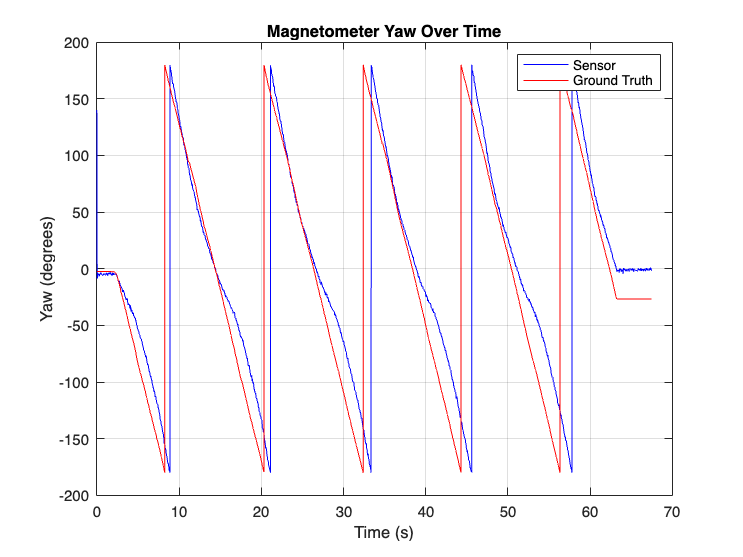

yaw_rad = atan2(mag_cal(:,2), mag_cal(:,3));
yaw_unwrapped = wrapToPi(yaw_rad);
yaw_deg = rad2deg(yaw_unwrapped);

q_GT = quaternion(GT_yaw);
eul = quat2eul(q_GT);
GT_yaw_unwrapped = wrapToPi(eul(:,1));
GT_yaw_deg = rad2deg(GT_yaw_unwrapped);  % Convert to degrees

figure;
plot(time_rot, yaw_deg, 'b', time_rot, GT_yaw_deg, 'r');
xlabel('Time (s)');
ylabel('Yaw (degrees)');
title('Magnetometer Yaw Over Time');
legend('Sensor', 'Ground Truth')
grid on;

rmse_mag(yaw_deg, GT_yaw_deg);

Yaw RMSE: 28.90 degrees



% Store into output params
A_mag = A;
b_mag = b;

disp('------End of Magnetometer calibration------')

------End of Magnetometer calibration------


### Output Params

save(outputFileName, 'accel_bias', 'accel_var', 'gyro_bias', 'gyro_var', 'A_mag', 'b_mag', 'tof_bias', 'tof_var');
    disp('Calibration successful! Saved parameters for:');

Calibration successful! Saved parameters for:


    disp(['  Accel bias: ', mat2str(size(accel_bias)), ', Accel variance: ', mat2str(size(accel_var))]);

  Accel bias: [1 3], Accel variance: [1 3]


    disp(['  Gyro bias: ', mat2str(size(gyro_bias)), ', Gyro variance: ', mat2str(size(gyro_var))]);

  Gyro bias: [1 3], Gyro variance: [1 3]


    disp(['  Magnetometer - A: ', mat2str(size(A_mag)), ', b: ', mat2str(size(b_mag))]);

  Magnetometer - A: [3 3], b: [1 3]


    disp(['  ToF biases: ', mat2str(size(tof_bias)), ', ToF variance: ', mat2str(size(tof_var))]);

  ToF biases: [1 3], ToF variance: [1 3]


## Helper Functions

%% TOF %%
function [x_offset, theta_rad] = optimizeOffsetLR(gt_xy, tof_left_vec, tof_right_vec, L)
    assert(size(gt_xy, 1) == length(tof_left_vec), 'Length mismatch');

    % Initial guess: [x_offset, theta]
    x0 = [0.05; 0];

    % Residual over all time steps
    residual = @(p) arrayfun(@(i) ...
        compute_residual_i(p, gt_xy(i,:), tof_left_vec(i), tof_right_vec(i), L), ...
        1:length(tof_left_vec), 'UniformOutput', false);

    % Flatten residuals
    residual_flat = @(p) cell2mat(residual(p)');

    % Solve
    options = optimoptions('lsqnonlin', 'Display', 'iter', 'MaxFunctionEvaluations', 2000);
    p_opt = lsqnonlin(residual_flat, x0, [], [], options);

    % Output
    x_offset = p_opt(1);
    theta_rad = p_opt(2);
    fprintf('\nEstimated lateral offset: %.4f m\n', x_offset);
    fprintf('Estimated yaw angle: %.4f rad (%.2f deg)\n', theta_rad, rad2deg(theta_rad));
end

function err = compute_residual_i(p, robot_pos, T_left, T_right, L)
    x_offset = p(1);
    theta = p(2);

    % Wall x-positions
    wall_left_x = -L / 2;
    wall_right_x = L / 2;

    % Rotation matrix
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];

    % Sensor positions in world frame
    pos_left  = robot_pos + (R * [-x_offset; 0])';
    pos_right = robot_pos + (R * [ x_offset; 0])';

    % Sensor directions
    n_left  = R * [-1; 0];
    n_right = R * [ 1; 0];

    % Expected ToF readings (projected distance to walls)
    expected_left  = (wall_left_x  - pos_left(1)) / n_left(1);
    expected_right = (wall_right_x - pos_right(1)) / n_right(1);

    % Residuals
    err = [expected_left - T_left; expected_right - T_right];
end

function front_bias = optimizeOffsetF(gt_xy, tof_front, theta, y_wall, front_offset)
    front_offset = [0, 0];

    % Rotation matrix
    R = [cos(theta), -sin(theta); sin(theta), cos(theta)];

    % Sensor rotated forward unit vector
    n_front = R * [0; 1];

    % World frame sensor positions
    N = size(gt_xy, 1);
    sensor_pos = gt_xy + (R * front_offset')';  % Nx2

    % Expected distance based on geometry (projected to front direction)
    expected_tof = (y_wall - sensor_pos(:,2)) / n_front(2);

    % Solve bias with least squares
    front_bias = mean(tof_front - expected_tof);

    fprintf('\nFront ToF offset: %.4f m\n', front_bias);
end

function [calib_left, calib_right, calib_front] = applyToFCalibration(tof_bias, theta_offset, tof1, tof2, tof3)
    % Sensor directions (in robot frame)
    n_left  = [-1; 0];
    n_right = [1; 0];
    n_front = [0; 1];

    % Rotation matrix
    R = [cos(theta_offset), -sin(theta_offset); sin(theta_offset), cos(theta_offset)];

    % Rotated directions (unit vectors)
    dL = R * n_left;
    dR = R * n_right;
    dF = R * n_front;

    % Correct each ToF reading: remove bias and project along corrected angle
    calib_left  = (tof1  - tof_bias(1)) .* dL(1);  % Project onto X
    calib_right = (tof2  - tof_bias(2)) .* dR(1);  % Project onto X
    calib_front = (tof3  - tof_bias(3)) .* dF(2);  % Project onto Y
end

function filtered = butterworth(data, fs, fc)
    fs = fs;           % Sampling frequency (Hz) = 50 originally
    fc = fc;           % Cutoff frequency (Hz) = 0.1 originally
    order = 2;         % Filter order
    
    Wn = fc/(fs/2);
    [b, a] = butter(order, Wn, 'low');
    
    % Apply zero-phase filtering (no phase shift)
    filtered = filtfilt(b, a, data);
end

%% MAGNETOMETER %%
function rmse_mag(yaw_deg, GT_yaw_deg)
    yaw_error = yaw_deg - GT_yaw_deg;
    yaw_error = mod(yaw_error + 180, 360) - 180;
    rmse_yaw = sqrt(mean(yaw_error.^2));
    fprintf('Yaw RMSE: %.2f degrees\n', rmse_yaw);
end

function angle = wrapToPi(angle)
    angle = mod(angle + pi, 2*pi) - pi;
end